% ================ 注释中英文对照，供阅读比较================
% 优化回归树
% 使用 fitrtree 自动优化超参数。
% Optimize Regression Tree
% Optimize hyperparameters automatically using fitrtree.

% Load the carsmall data set.
load carsmall
% 使用重量和马力作为 MPG 的预测指标。 
X = [Weight,Horsepower];
Y = MPG;

## 训练回归树

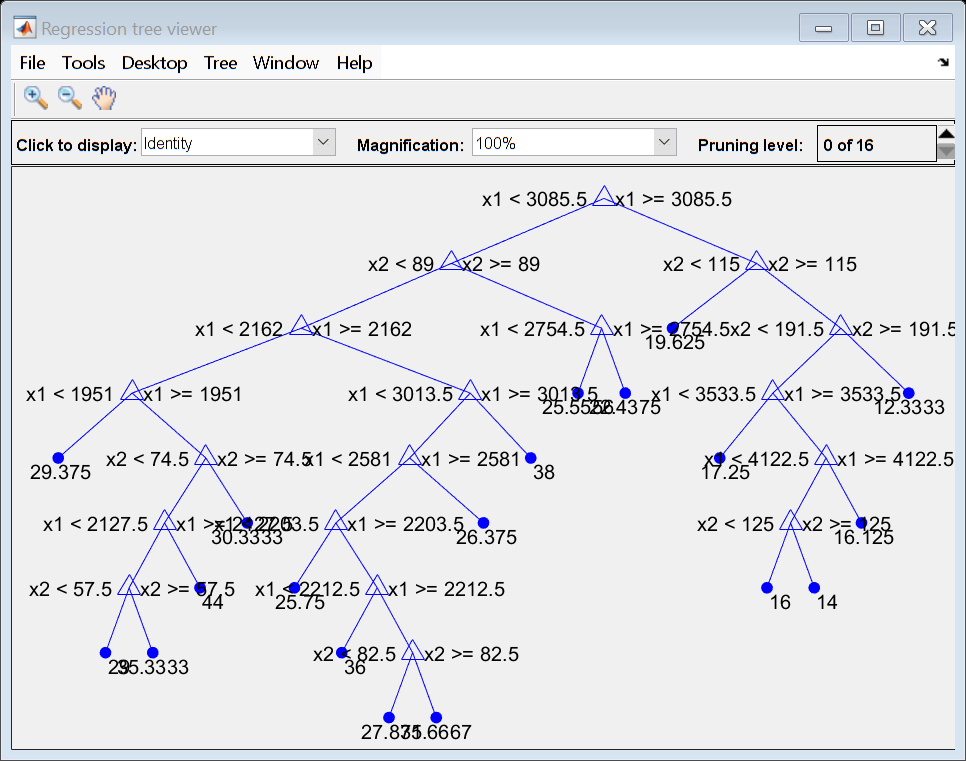

Md0 = fitrtree(X,Y);
view(Md0,'Mode','graph')

% 计算训练集的损失函数
resubLoss(Md0)  %  5.8158

ans = 5.8158

% 计算训练集的误差平方的均值（均方误差）
Y0_pre=predict(Md0,X);
mean((Y0_pre-Y).^2) % 缺失值没有处理

ans = NaN

## 通过使用fitrtree的自动超参数优化，

找到将五倍交叉验证损失最小化的超参数。 为了重现性，设置随机种子并使用“预期改进加”采集功能。 Use Weight and Horsepower as predictors for MPG. Find hyperparameters that minimize five-fold cross-validation loss by using automatic hyperparameter optimization. For reproducibility, set the random seed and use the 'expected-improvement-plus' acquisition function.

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      3.2818 |    0.078052 |      3.2818 |      3.2818 |           28 |
|    2 | Accept |      3.4183 |    0.042363 |      3.2818 |      3.2888 |            1 |
|    3 | Best   |      3.1457 |    0.039174 |      3.1457 |      3.1628 |            4 |
|    4 | Best   |      2.9885 |    0.060411 |      2.9885 |      2.9885 |            9 |
|    5 | Accept |      2.9978 |    0.024709 |      2.9885 |      2.9885 |            7 |
|    6 | Accept |      3.0203 |    0.023016 |      2.9885 |      3.0013 |            8 |
|    7 | Accept |      2.9885 |    0.022924 |      2.9885 |      2.9981 |            9 |
|    8 | Best   |    

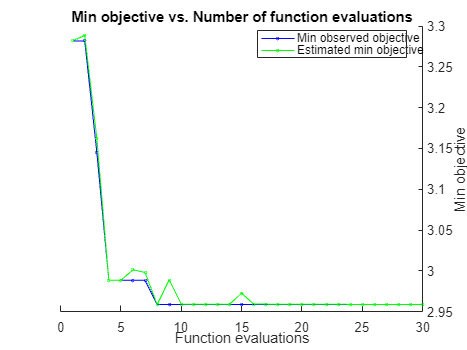

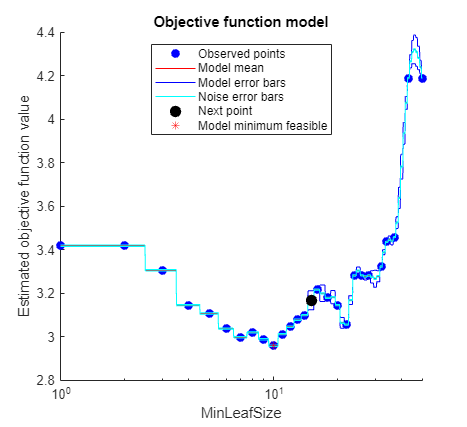

Md1 =   RegressionTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                      NumObservations: 94
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


rng default
Md1 = fitrtree(X,Y,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

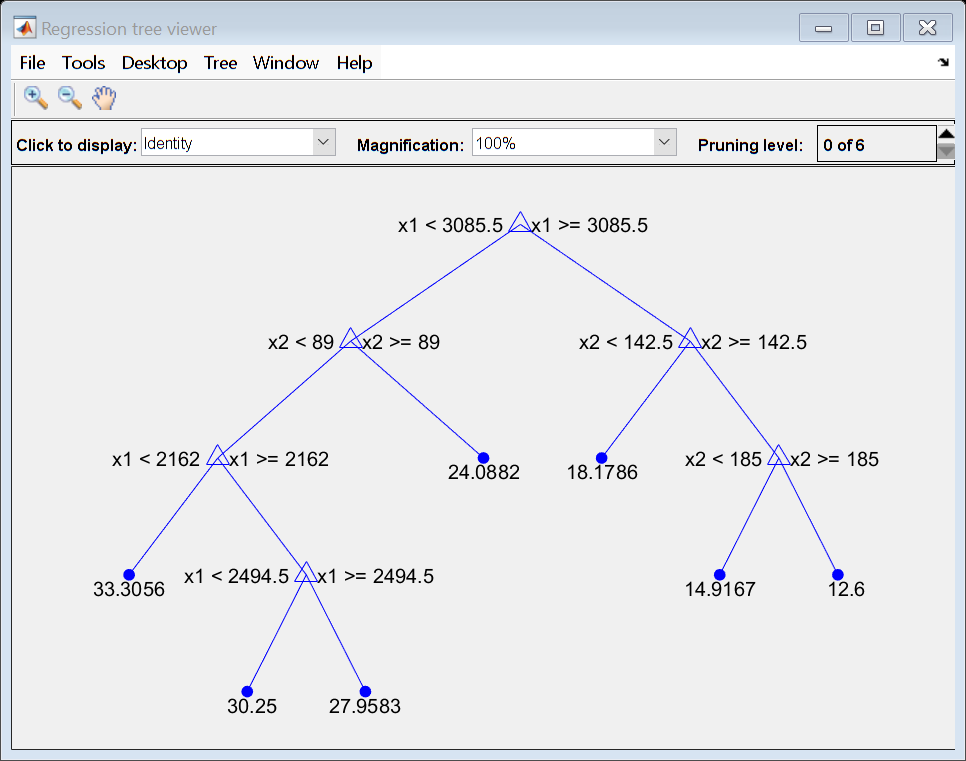

view(Md1,'Mode','graph')

resubLoss(Md1) % 12.1673

ans = 12.1673

% 计算训练集的误差平方的均值（均方误差）
Y1_pre=predict(Md1,X);
mean((Y1_pre-Y).^2) % 缺失值没有处理

ans = NaN


% 模型结构大大精简了，训练集的性能下降了